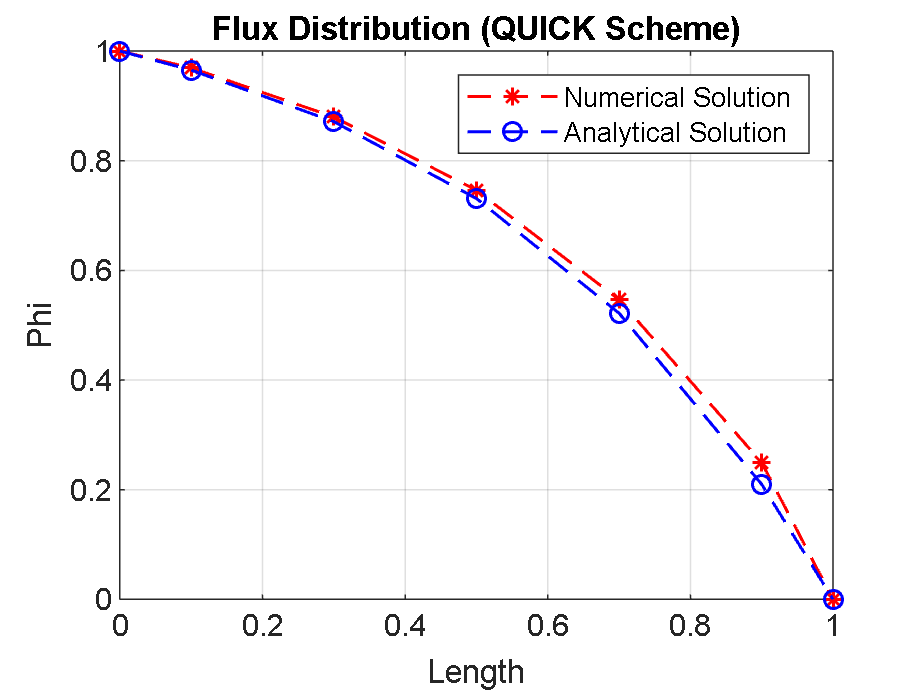

% Setting Variables
n = 5; % Number of control volumes
L = 1; % Total length
gamma = 0.1; % Diffusion coefficient
v_in = 0.2; % Inlet velocity
phi1 = 1; % Boundary condition at left face
phi0 = 0; % Boundary condition at right face
rho = 1; % Density
guess = 1; % Initial guess for phi
m = 1000; % Number of iterations

%% Call QUICK Scheme function
[x, phi_N] = QUICK(L, gamma, v_in, phi1, phi0, rho, n, guess, m); % Call the QUICK function to obtain numerical solution

%% Analytical solution from book
phiactual = [1.0000, 0.9653, 0.8713, 0.7311, 0.5218, 0.2096, 0]; % Analytical solution values provided

% Plot numerical and analytical solutions
figure;
plot(x, phi_N, "r*--", LineWidth=1); % Plot numerical solution with red asterisks and dashed line
hold on;
plot(x, phiactual, "bo--", LineWidth=1); % Plot analytical solution with blue circles and dashed line
xlabel('Length'); % Label x-axis
ylabel('Phi'); % Label y-axis
title('Flux Distribution (QUICK Scheme)'); % Plot title
legend('Numerical Solution', 'Analytical Solution'); % Legend
grid on; % Turn on grid lines

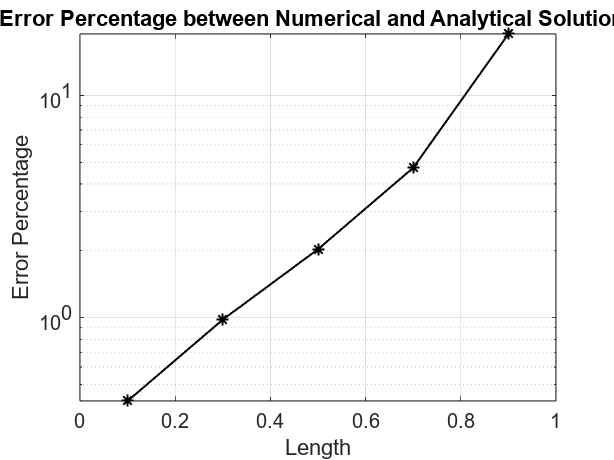


% Calculate and plot error percentage
error_percentage = 100 * abs((phi_N(1:end-1) - phiactual(1:end-1)) ./ phiactual(1:end-1)); % Calculate error percentage, excluding last point

figure;
semilogy(x(1:end-1), error_percentage, "k*-", LineWidth=1); % Plot error percentage on a semi-log scale with black asterisks and solid line
xlabel('Length'); % Label x-axis
ylabel('Error Percentage'); % Label y-axis
title('Error Percentage between Numerical and Analytical Solutions'); % Plot title
grid on; % Turn on grid lines


% Display mean error percentage
mean_error = mean(error_percentage); % Calculate mean error percentage
disp(['Mean Error Percentage: ', num2str(mean_error), '%']); % Print mean error percentage

Mean Error Percentage: 4.5165%


function [x, phi_N] = QUICK(L, gamma, v_in, phi1, phi0, rho, n, guess, m)

    dx = L / n; % Cell spacing
    x(1) = 0; % Initialize x coordinates for plotting
    x(2) = dx / 2;
    for i = 3:n+1
        x(i) = x(i-1) + dx; % Generate x coordinates for interior points
    end
    x(n+2) = L; % Set the final x value to the total length

    % Initialize arrays
    dxw = zeros(1, n+2); % West neighbor distance
    dxe = zeros(1, n+2); % East neighbor distance
    phi_N = guess * ones(1, n+2); % Array to store numerical phi values, initialized with the initial guess
    Fw = zeros(1, n+2); % Convection term at west face
    Fe = zeros(1, n+2); % Convection term at east face
    Dw = zeros(1, n+2); % Diffusion term at west face
    De = zeros(1, n+2); % Diffusion term at east face

    Pe = rho * v_in / (gamma / dx); % Peclet number
    P = rho * v_in / (gamma / L); % Dimensionless parameter

    for i = 2:n+1 % Calculate neighbor distances and convection terms
        dxw(i) = (x(i) - x(i-1)); % Distance to west neighbor
        dxe(i) = (x(i+1) - x(i)); % Distance to east neighbor
        Fe(i) = rho * v_in; % East face convection
        Fw(i) = rho * v_in; % West face convection (same inlet velocity)
        De(i) = gamma / dxe(i); % East face diffusion
        Dw(i) = gamma / dxw(i); % West face diffusion
    end

    % Initialize coefficients for tridiagonal matrix system
    aww = zeros(1, n+2); % West-west face coefficient
    aw = zeros(1, n+2); % West face coefficient
    ae = zeros(1, n+2); % East face coefficient
    aee = zeros(1, n+2); % East-east face coefficient
    ap = zeros(1, n+2); % Diagonal coefficient
    d = zeros(1, n+2); % Right-hand side of the system
    a = zeros(1, n+2); % Lower diagonal coefficient
    b = zeros(1, n+2); % Upper diagonal coefficient
    aa = zeros(1, n+2); % Lower-lower diagonal coefficient
    bb = zeros(1, n+2); % Upper-upper diagonal coefficient
    c = zeros(1, n+2); % Source terms

    alphaw = zeros(1, n+2); % Upwind weighting factor for west face
    alphae = zeros(1, n+2); % Upwind weighting factor for east face

    for i = 3:n
        % Determine upwind weighting factors
        if Fw(i) > 0
            alphaw(i) = 1;
        else
            alphaw(i) = 0;
        end
        if Fe(i) > 0
            alphae(i) = 1;
        else
            alphae(i) = 0;
        end

        % Calculate coefficients for interior nodes using QUICK scheme
        aww(i) = alphaw(i) * (-Fw(i) / 8);
        aw(i) = Dw(i) + alphaw(i) * (6 * Fw(i) / 8) + alphae(i) * (Fe(i) / 8) + (1 - alphaw(i)) * (3 * Fw(i) / 8);
        aee(i) = (1 - alphae(i)) * (Fe(i) / 8);
        ae(i) = De(i) - (1 - alphae(i)) * (6 * Fe(i) / 8) - (1 - alphaw(i)) * (Fw(i) / 8) - alphae(i) * (3 * Fe(i) / 8);
        ap(i) = aw(i) + ae(i) + Fe(i) - Fw(i);
    end

    % Boundary conditions
    if Pe >= 0 % Left to right flow
        aw(2) = Dw(2) + Fw(2) + (Fe(2) / 3); % West face coefficient at left boundary
        ae(2) = De(2) - (Fe(2) / 3); % East face coefficient at left boundary
        aww(3) = (-Fw(3) / 3); 
        aw(3) = Dw(3) + Fw(3) + (Fe(3) / 8); % West face coefficient at second interior node
        ae(3) = De(3) - (3 * Fe(3) / 8); % East face coefficient at second interior node
        aww(n+1) = (-Fw(n+1) / 8); 
        aw(n+1) = Dw(n+1) + (6 * Fw(n+1) / 8); % West face coefficient at right boundary
        ae(n+1) = De(n+1) - Fe(n+1); % East face coefficient at right boundary
    else % Right to left flow
        ae(n+1) = De(n+1) - Fe(n+1) - (Fw(n+1) / 3); % East face coefficient at right boundary
        aw(n+1) = Dw(n+1) + (Fw(n+1) / 3); % West face coefficient at right boundary
        aee(n) = (+Fe(n) / 3); 
        ae(n) = De(n) - Fe(n) - (Fw(n) / 8); % East face coefficient at second-last interior node
        aw(n) = Dw(n) + (3 * Fw(n) / 8); % West face coefficient at second-last interior node
        aee(2) = (+Fe(2) / 8); 
        ae(2) = De(2) - (6 * Fe(2) / 8); % East face coefficient at left boundary
        aw(2) = Dw(2) + Fw(2); % West face coefficient at left boundary
    end

    for i = 2:n+1
        ap(i) = aww(i) + aw(i) + ae(i) + aee(i) + Fe(i) - Fw(i); % Diagonal coefficient
        a(i) = -ae(i); % Lower diagonal coefficient
        b(i) = -aw(i); % Upper diagonal coefficient
        aa(i) = -aee(i);
        bb(i) = -aww(i); 
        d(i) = ap(i); % Right-hand side of the system
    end

    % Apply boundary conditions
    ap(1) = 1; % Diagonal coefficient at left boundary
    c(1) = phi1; % Source term at left boundary
    ap(n+2) = 1; % Diagonal coefficient at right boundary
    c(n+2) = phi0; % Source term at right boundary

    % Initialize solution at boundaries
    phi_N(1) = c(1) / ap(1); % Solution at left boundary
    phi_N(n+2) = c(n+2) / ap(n+2); % Solution at right boundary

    for j = 1:m % Iterative solution
        phi_N(2) = (1 / ap(2)) * (aw(2) * phi_N(1) + ae(2) * phi_N(3) + aee(i) * phi_N(4)); % Solution at second node
        for i = 3:n % Solution for interior nodes
            phi_N(i) = (1 / ap(i)) * (aww(i) * phi_N(i-2) + aw(i) * phi_N(i-1) + ae(i) * phi_N(i+1) + aee(i) * phi_N(i+2));
        end
        phi_N(n+1) = (1 / ap(n+1)) * (aww(n-1) * phi_N(n) + aw(i) * phi_N(n) + ae(i) * phi_N(n+2)); % Solution at second-last node
    end
end